# Change variables from MATLAB

## Clean up variables and RoadRunner

if exist("rrApp", "var")
    if class(rrApp) == "roadrunner"
        rrApp.close();
    end
end
if exist("rrSim", "var")
    delete(rrSim);
end
close all;
clear; 

## Launch RoadRunner from MATLAB

rrApp = roadrunner();

% Open a scenario with pre-created variables
rrProjectPath = rrApp.status.Project.Filename;
copyfile("RRfiles/CutInAndSlowWithVariables.rrscenario",fullfile(rrProjectPath,"Scenarios/"))
openScenario(rrApp,"CutInAndSlowWithVariables") 

## Change one scenario variable

Access a scenario variable ("Gap") prepared in the sample scenario 

name = "Gap";
value = 16; %[m]

% Change scenario variable value
setScenarioVariable(rrApp,name,value);

% Get scenario variable value
getScenarioVariable(rrApp,name) 

ans = '16'

## Create a scenario variable

Refer to the video below to create a new scenario variable in RoadRunner 

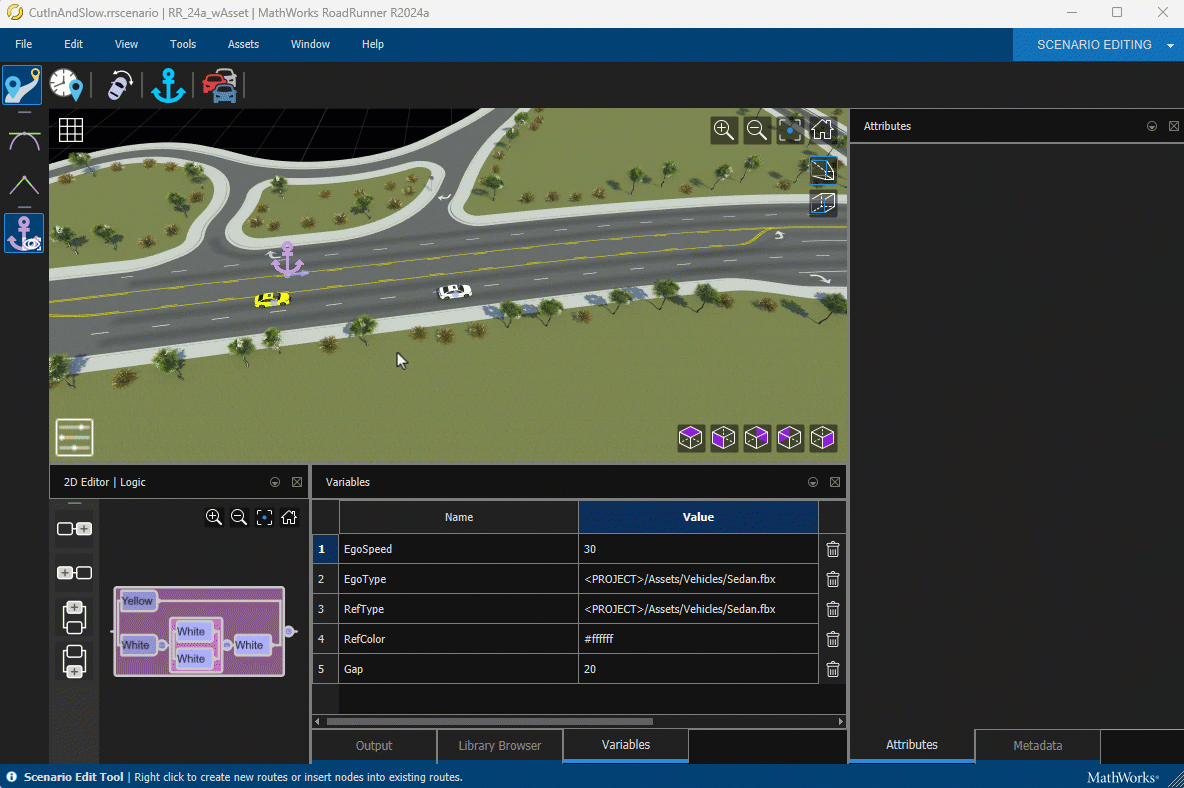

% Let's change the variable values we created from MATLAB.
% setScenarioVariable(rrApp,"YourVariable","Value"); % Please uncomment and try

## Get a list of all scenario variables

It is also possible to get a list of what variables are defined in the open scenario 

% Get all variables from RoadRunner
rrvars = getAllScenarioVariables(rrApp)

rrvars = 5×1 struct array with fields:
    Name
    Value
    TypedValue


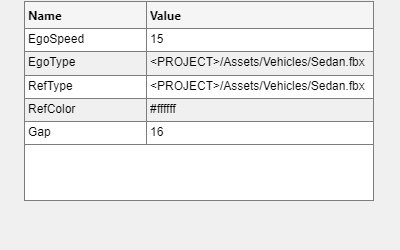

% Change variable values using a simple UI
data = rmfield(rrvars,"TypedValue");
fig = uifigure('Position',[100 100 400 250]);
uit = uitable('Parent',fig,'Position',[25 50 350 200]);
uit.Data = struct2table(data);
uit.DisplayDataChangedFcn = @(src,event) updateScenario(src, rrApp);
uit.ColumnEditable = [false true]; 

## Generate variations

Access to scenario variables can also be used to generate variations 

Here we will perform simple parameter assignment and visualization of the results 

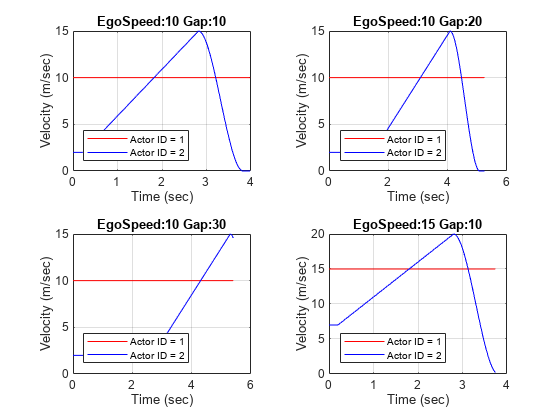

% Set variation
egoSpeedList = [10 15];
gapList = [10 20 30];

rrSim = rrApp.createSimulation();

% Simulation pacing off
set(rrSim, "PacerStatus", "Off")

% Turn on log acquisition setting
set(rrSim,"Logging","on");

tiledlayout("flow");
for egoSpeed = egoSpeedList
    for gap = gapList

        % Change scenario variable value
        setScenarioVariable(rrApp,"EgoSpeed",egoSpeed);
        setScenarioVariable(rrApp,"Gap",gap);
        
        % Run simulation
        set(rrSim,"SimulationCommand","Start");
        while strcmp(get(rrSim,"SimulationStatus"),"Running")
            pause(1);
        end
        
        % Get log
        rrLog = get(rrSim,"SimulationLog");
        
        % Get vehicle speed
        velocityAgent1 = get(rrLog,'Velocity','ActorID',1); % Get speed of Actor1
        velocityAgent2 = get(rrLog,'Velocity','ActorID',2); % Get speed of Actor2
        time = [velocityAgent1.Time];% Get time of Actor1
        
        % Plot vehicle speed
        nexttile;
        helperPlotVelocity(time, velocityAgent1, velocityAgent2);
        title("EgoSpeed:"+string(egoSpeed)+" Gap:"+string(gap));

        % Export to OpenSCENARIO XML
        %filename = "EgoSpeed_" + string(egoSpeed) + "_Gap_" + string(gap);
        %exportScenario(rrApp,filename,"OpenSCENARIO");

    end
end 

Support functions 

% uitable callback
function updateScenario(src, rrApp)
numParams = size(src.Data,1);
    for n = 1:numParams
        varname  = src.Data.Name{n};
        varvalue = src.Data.Value{n};
        setScenarioVariable(rrApp, varname, varvalue);
    end
end

% plotting velocity
function helperPlotVelocity(time, velocityAgent1, velocityAgent2)
    velMagAgent1 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent1);
    velMagAgent2 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent2);

    % Plot the agent velocities with respect to simulation time using the plot function. Label the graph and the x and y axes.
    %figure
    plot(time,velMagAgent1,"r")
    hold on
    plot(time,velMagAgent2,"b")
    hold off
    grid on
    title("Agent Velocities from RoadRunner Scenario")
    ylabel("Velocity (m/sec)")
    xlabel("Time (sec)")
    legend("Actor ID = 1","Actor ID = 2",'Location','southwest')
end
